# 作业题

本测试题设计30分钟完成.

`第1题 基础题`

`附件` “Homework1_ZZ50_2019_Aug_Sept.csv” `是上证`50`成分股`2019`年`8, 9`月的股票价格`.

- `求每个股票的对数收益率`, `找到`8`月和`9`月收益率最高的`5`个股票`.

- `观察`2`个月收益率最高的`5`个股票是否相同`.

- `假如把标准放宽到`15`个`, `有几个股票`9`月仍然是收益率最高的`.

- `表述资产分散化的启示`.

- `假设你是一个基金经理`, `在`8`月最后一个交易日收盘时买入股票`. `将你的`150 `万元资金等权重分配给`8`月收益率最高的`15`个股票`. `计算你`9`月的收益率`. `考虑``取整问题`**: **`股票市场的交易规则是以`**100**`股作为最小买卖单位`**.**

- `求收盘价的线性相关性矩阵`, `并画出热力图`, `发现相关性较大的股票`.

- `求收益率的线性相关性矩阵`, `并画出热力图`, `分析这两张图不同的原因`.

- `挑一组收益率相关性较高的股票`, `分析可能的原因`.

- `表述构建投资组合时`, `对相关性要注意什么`.

**解答**

对数收益率.

clear
close all

data = readtable("Homework1_ZZ50_2019_Aug_Sept.csv");
% 42个交易日, 50个股票.
price = reshape(data.close, [42, 50]);
% 8月22个交易日, 9月20个交易日. 求收益率.
AugRate = log(price(22, :)) - log(price(1, :));
SeptRate = log(price(42, :)) - log(price(22, :));

收益率最大的5个股票.

% 找到收益率最大的5个股票.
[~, AugIdx] = sort(AugRate);
[~, SeptIdx] = sort(SeptRate);
BestAug = AugIdx(46:50);
BestSept = SeptIdx(46:50);
Repeat_5 = OneInAnother(BestAug, BestSept)


Repeat_5 =

     []



标准放宽到15个.

% 扩大到15个股票.
BestAug = AugIdx(36:50);
BestSept = SeptIdx(36:50);
Repeat_15 = OneInAnother(BestAug, BestSept)

Repeat_15 =     20    10    17    22


等权重分散化的基金.

% 150万元15个股票以1手为单位 = 1000元每个股票以1股为单位
Amount = 1000 ./ price(22, BestAug);
Amount = floor(Amount);
Profit = sum(Amount .* (price(42, BestAug) - price(22, BestAug)) ./ 1.5e4)

Profit = -0.0028

相关性矩阵.

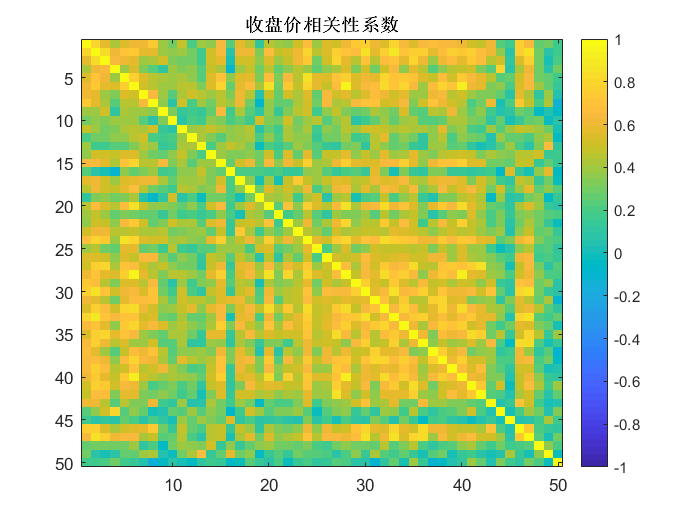

% 要考虑收益率相关性较低的股票构建资产组合, 否则不能体现分散化的优势.
figure
intr = diff(log(price));
corr_ = corrcoef(intr);

imagesc(corr_);
title("收盘价相关性系数")
caxis([-1 1])
colorbar

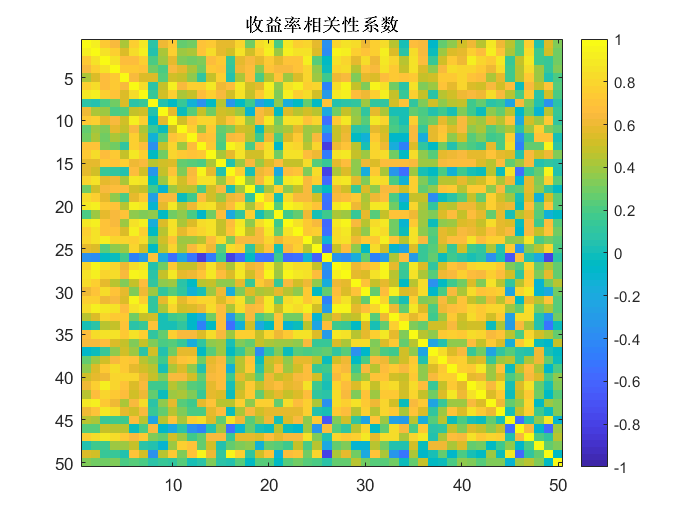

figure
corr_ = corrcoef(price);

imagesc(corr_);
title("收益率相关性系数")
caxis([-1 1])
colorbar

`第`2`题 探究题`

`附件` “WTI_crude_oil_futures.csv” `是`WTF`国际原油期货`2020.4.11~2020.5.11`的价格`, `注意部分价格位于``负区间`. 

- `分析数据中` “rate” `收益率是如何计算的`.

- `提出一种` “`等效对数收益率`”, `解决在负价格区间上求对数收益率`, `并提交结果`.

**解答:**

读取数据.

clear
close all

price = readtable("WTI_crude_oil_futures.xlsx");

对数收益率.

rtn_clx = diff(log(price.close));

负价格的收益率出现复数, 取绝对值.

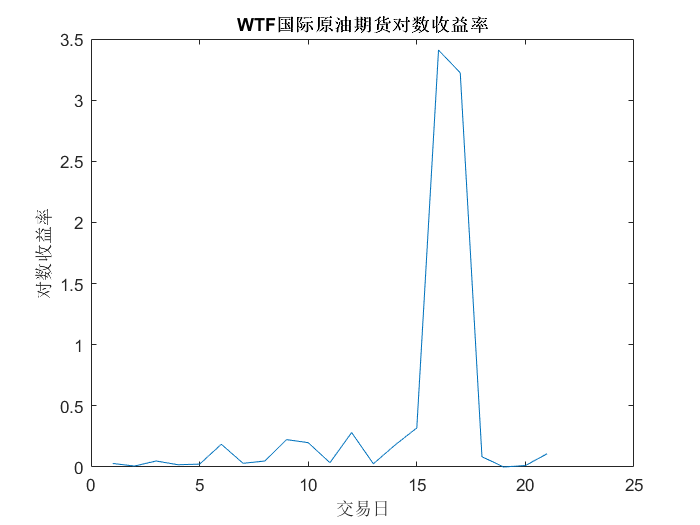

rtn = abs(rtn_clx);
plot(rtn);
title("WTF国际原油期货对数收益率")
xlabel("交易日")
ylabel("对数收益率")

函数体

function Element = OneInAnother(vec1, vec2)
Element = [];
for x = vec1
    for y = vec2
        if x == y
            Element(end+1) = x;
            break
        end
    end
end
end